# Preprocess the data

**rat010_0615**: most neurons good; 7th much better(max: 0.0086)

**rat009_0625**: fair

close all;clear;clc;

## spike time to spike train

load("data/data_rat010_0615_spike.mat")

timebins  = 0.01; % 10ms time bins
threshold = 0; % at least 1 spike

spikeLength = 1e7;
M1num       = 0;
mPFCnum     = 0;
for channelNo = 1:32
  for sub = ['a', 'b']
    channelName = ['WB', num2str(channelNo, '%02d'), sub];
    if (~exist(channelName, "var"))
      continue;
    end
    if (channelNo <= 16)
      M1num     = M1num + 1;
    else
      mPFCnum   = mPFCnum + 1;
    end
    spikeLength = min(spikeLength, ceil(max(eval(channelName))/timebins));
  end
end
M1   = zeros(spikeLength, M1num);
mPFC = zeros(spikeLength, mPFCnum);

M1i = 1; mPFCi = 1;
for channelNo = 1:32
  for sub = ['a', 'b']
    channelName = ['WB', num2str(channelNo, '%02d'), sub];
    if (~exist(channelName, "var"))
      continue;
    end
    
    spikeTrain = double(accumarray(fix(eval(channelName)*1/timebins)+1, 1) > threshold);
    if (channelNo <= 16)
      M1(:, M1i) = spikeTrain(1:spikeLength);
      M1i = M1i+1;
    else
      mPFC(:,mPFCi) = spikeTrain(1:spikeLength);
      mPFCi = mPFCi+1;
    end
  end
end

Mutual Information

p_M1_0   = sum(M1   == 0) / spikeLength;
p_M1_1   = sum(M1   == 1) / spikeLength;
p_mPFC_0 = sum(mPFC == 0) / spikeLength;
p_mPFC_1 = sum(mPFC == 1) / spikeLength;

p_00 = (M1==0)'*(mPFC==0) / spikeLength;
p_01 = (M1==0)'*(mPFC==1) / spikeLength;
p_10 = (M1==1)'*(mPFC==0) / spikeLength;
p_11 = (M1==1)'*(mPFC==1) / spikeLength;

MI = p_00.*log2(p_00./(p_M1_0'*p_mPFC_0)) + ...
     p_01.*log2(p_01./(p_M1_0'*p_mPFC_1)) + ...
     p_10.*log2(p_10./(p_M1_1'*p_mPFC_0)) + ...
     p_11.*log2(p_11./(p_M1_1'*p_mPFC_1));

Extract the best neurons

For rat010_0615, M1 7/11/13 neurons, mPFC 5/6/7/8/13 neurons are selected

M1neurons   = [7 11 17];
mPFCneurons = [5 6 7 8 13];
M1spike = M1(:, M1neurons);
mPFCspike = mPFC(:, mPFCneurons);
save("data/data_rat010_0615_spike_train_selected.mat", "M1spike", "mPFCspike")

Show results

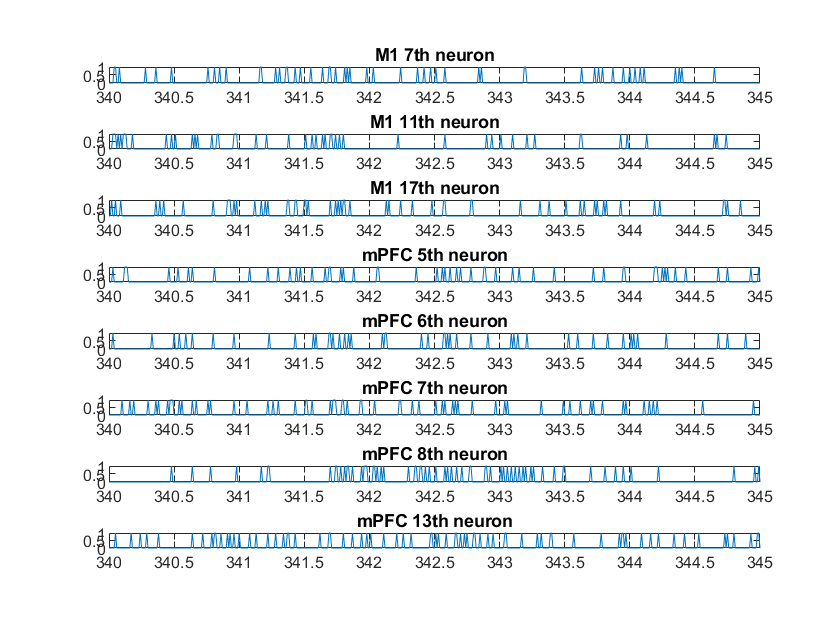

figure(1)
t=340:0.01:345;
for i=1:length(M1neurons)
    subplot(length(M1neurons)+length(mPFCneurons), 1, i)
    plot(t, M1spike(34000:34500, i))
    title(['M1 ', num2str(M1neurons(i)), 'th neuron'])
end
for i=1:length(mPFCneurons)
    subplot(length(M1neurons)+length(mPFCneurons), 1, i+length(M1neurons))
    plot(t, mPFCspike(34000:34500, i))
    title(strcat("mPFC ", num2str(mPFCneurons(i)), "th neuron"))
end